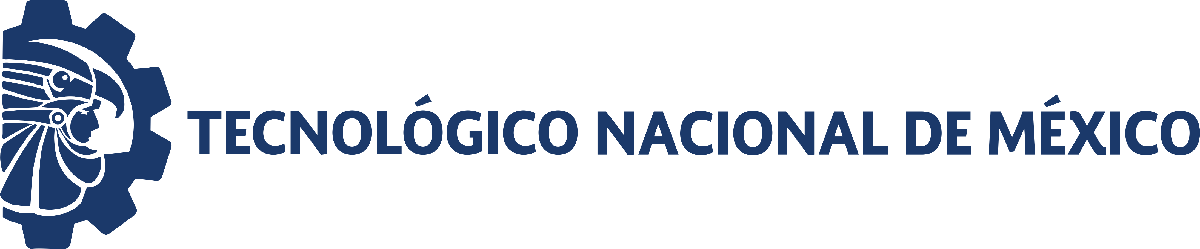                                 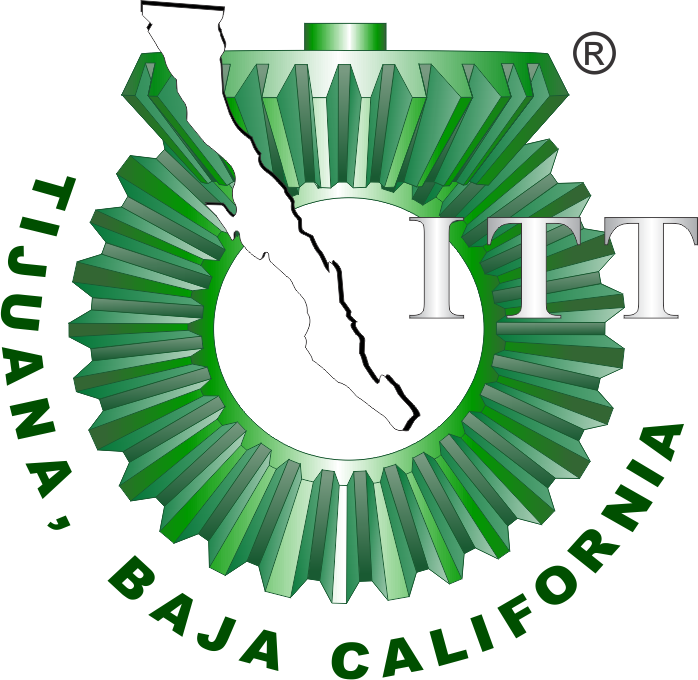

# Práctica Tres: Modelado y control del sistema musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

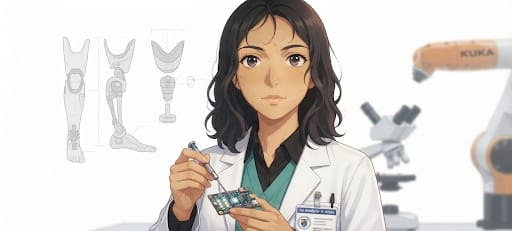

Nombre del alumno: Reyes Zamudio Mariant

Número de control: 23212228

Correo institucional: l23212228**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistema')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
% set_param('sistema/Vs(t): CE/Vs','VectorFormat','1-D array')

## Respuesta a la función 

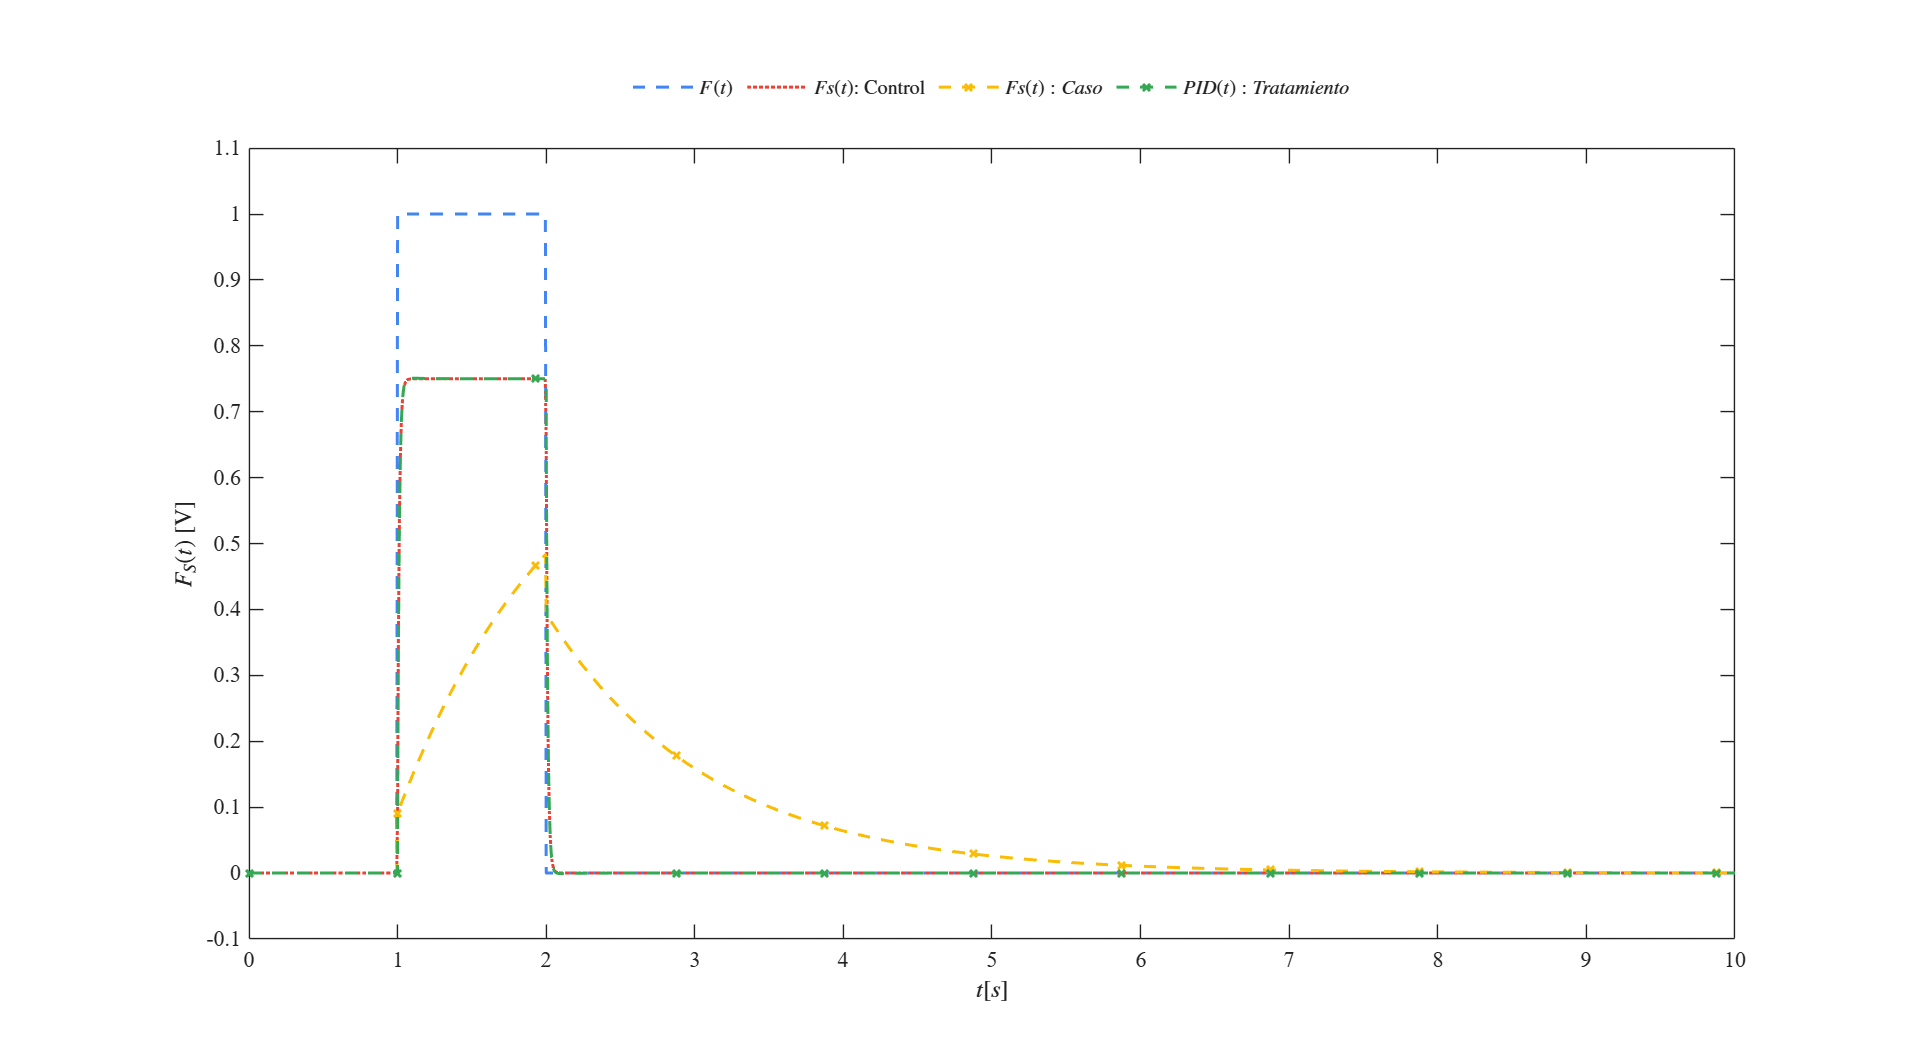

x = sim('sistema',parameters);
plotsignals(x.t,x.F,x.FsX,x.FsY,x.PID)

## **Función: Respuestas de la simulación**

function plotsignals(t,F,FsX,FsY,PID)
    set(figure(),'color','w')
    set(gcf,'units','inches','position', [1,1,18,8])
    set(gca, 'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [66, 133, 244]/255;  
    clr2 = [234, 67, 53]/255;   
    clr3 = [251, 188, 5]/255;   
    clr4 = [52, 168, 83]/255;
    order = [clr1; clr2; clr3; clr4]; colororder(order)

    plot(t,F,'--',t,FsX,':',t,FsY,'--x',t,PID,'--x','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
        1:1e3:length(t));

    L = legend('$F(t)$','$Fs(t)$: Control','$Fs(t): Caso$','$PID(t): Tratamiento$');
    set(L,'interpreter','latex','location','northoutside','orientation','horizontal', 'Box', 'off', 'NumColumns', 4)
  
    xlabel('$ t[s]$','Interpreter','latex')
    ylabel('$F_S(t)$ [V]', 'Interpreter','latex')

    xlim([0 10]); xticks(0:1:10)

    ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)
    exportgraphics(gcf, 'grafica_senales.pdf', 'ContentType', 'vector')
  
end